# Universidad de Guadalajara

## CUCEI

## Visión Robótica

## **Proyecto Final**

# Detección de esquinas y bordes en imagenes en Matlab

## ***Luis Angel Muñoz Franco***

## ***Angel***

***Introducción***

Consideremos el hecho de un robot que cuenta con una camara para detectar lo que tiene enfrente de el y un sensor ultrasonico para medir la distancia hacia ese objeto, considerando esto, se procede a implementar una serie de algoritmos y programas que le permitan al robot conocer los limites de estos objetos que encontrará en su camino, estos limites vendrán dados por los bordes del objeto y las esquinas.

El procesamiento en tiempo real de imagenes cuentra con la severa desventaja del tiempo computacional necesario para realizar estas tareas de procesamiento de imagenes, tomando esto en cuenta se procede a hacer lo siguiente buscando el mejor desempeño posible:

- conversión a escala de grises

- aplicación de filtro promedio

- hacemos la imagen de 1/4 de su tamaño original

- Aplicación de HDR

- Aplicamos filtro mediana para prevenir ruido

- hacemos canny

- Aplicamos opening y closing 

- hacemos detección de bordes y esquinas

## ***Desarrollo***

Para esta presentación solo consideraremos una imagen, pero el mismo resultado puede ser utilizado para una serie de imagenes o un video.

Primero leemos la imagen:

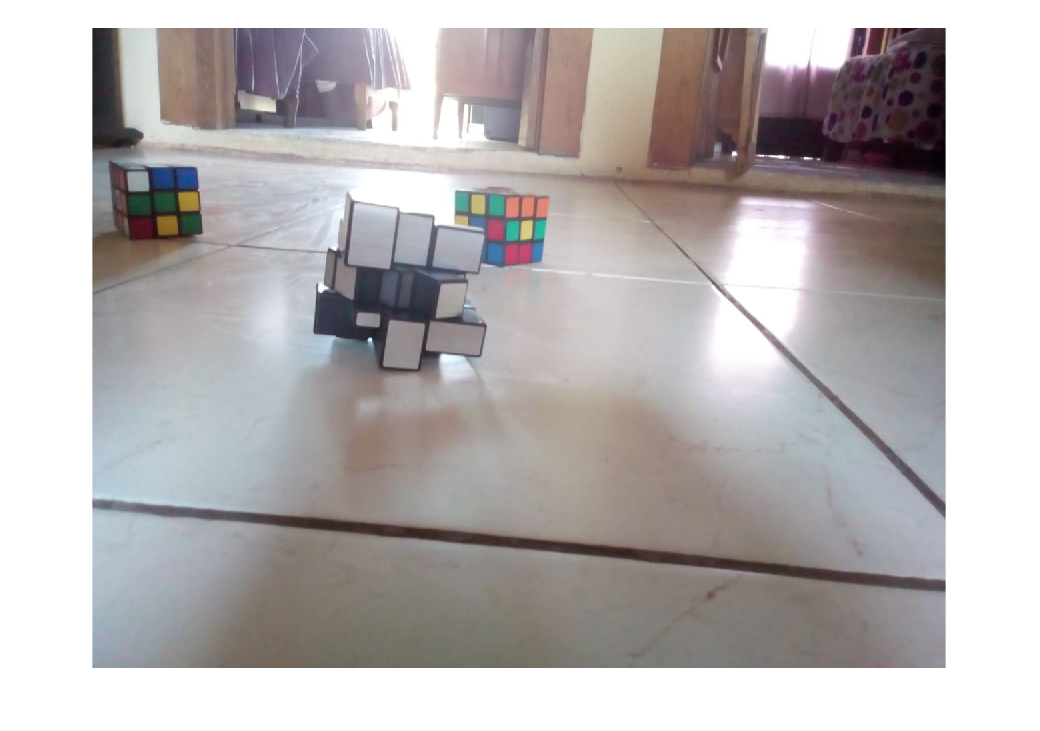

imOriginal = imread('im3.jpeg');
imshow(imOriginal)

Hacemos la conversión a escala de grises:

La conversión hace un promedio de los 3 colores de cada pixel.

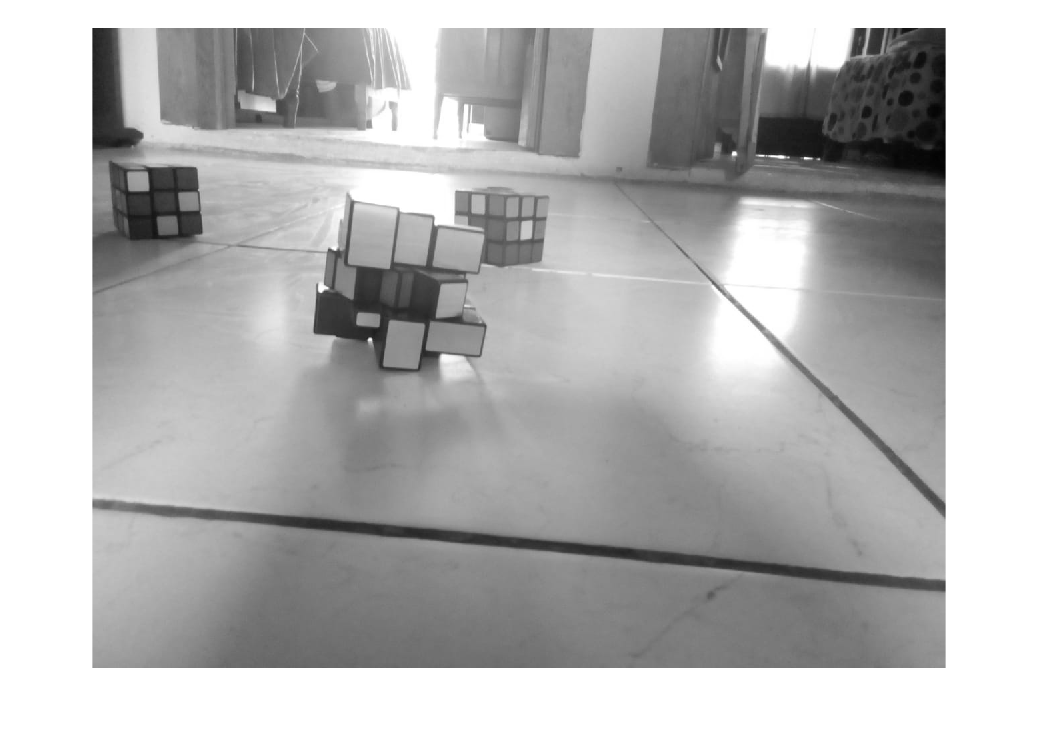

imGris = rgb2gray(imOriginal);
imshow(imGris)

Antes de disminuir el tamaño de la imagen conviene hacer un filtro para no perder parte de la información de la imagen, aplicaremos un filtro suavizador promedio para este efecto

**Filtro Promedio**

utilizamos el siguiente filtro:

h = ones(3)/9;

Realizamos la convolución de la imagen con el filtro para obtener la imagen con el filtro aplicado:

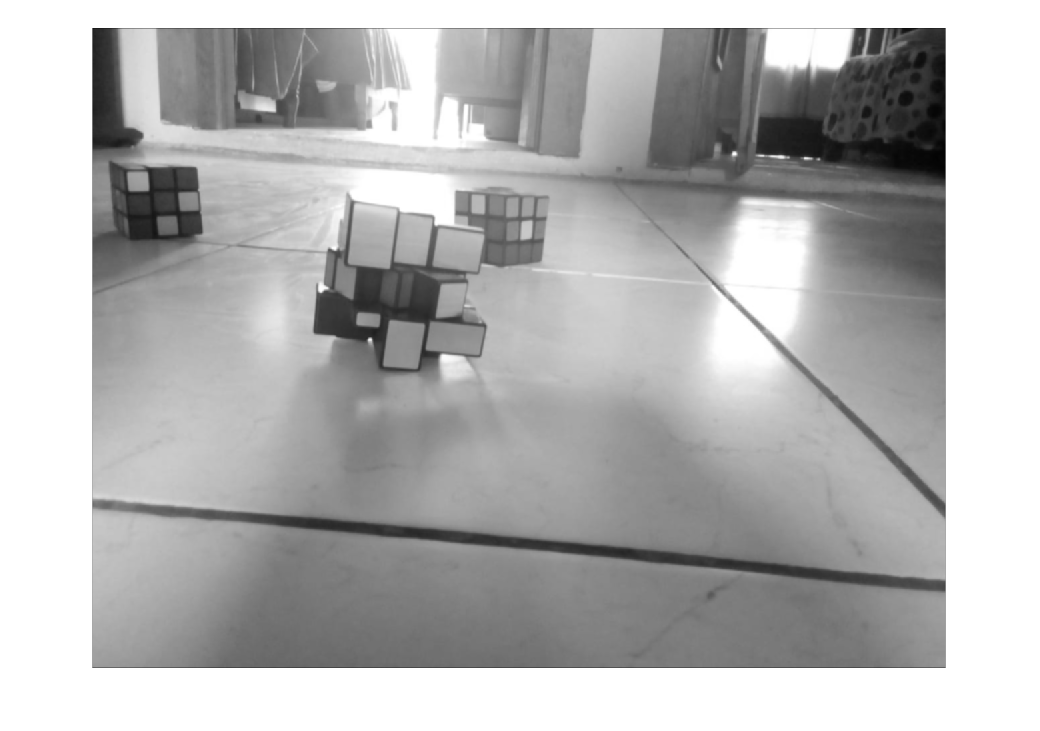

imFiltrada = uint8(conv2(imGris,h,'same'));
imshow(imFiltrada)

**Reducción de tamaño**

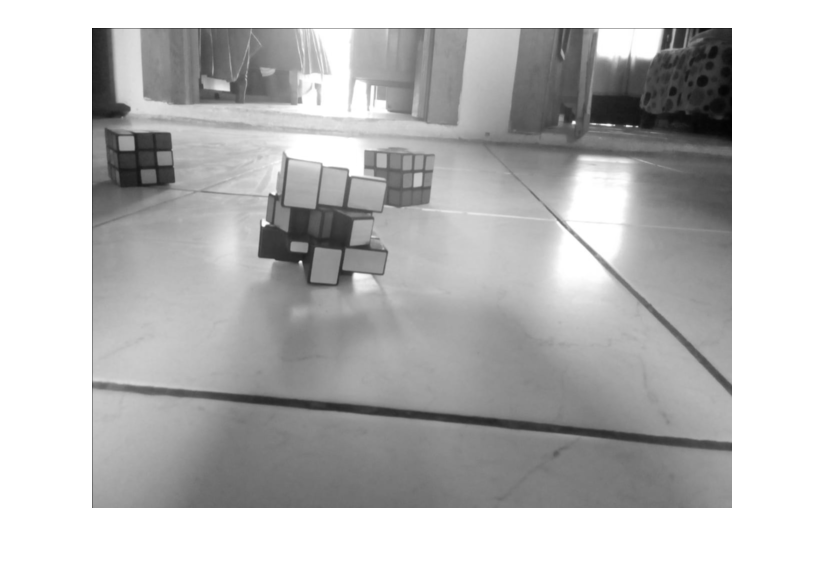

imReducida = imFiltrada(1:2:end,1:2:end);
imshow(imReducida)

**Aplicación de HDR a la imagen**

Para aplicar HDR es necesario hacer los siguientes pasos con la imagen en escala de grises:

- Calcular Histograma

- Normalizar la imagen

- Ecualizar la imagen

- Calcular HDR

Primero calculamos el histograma de la imagen:

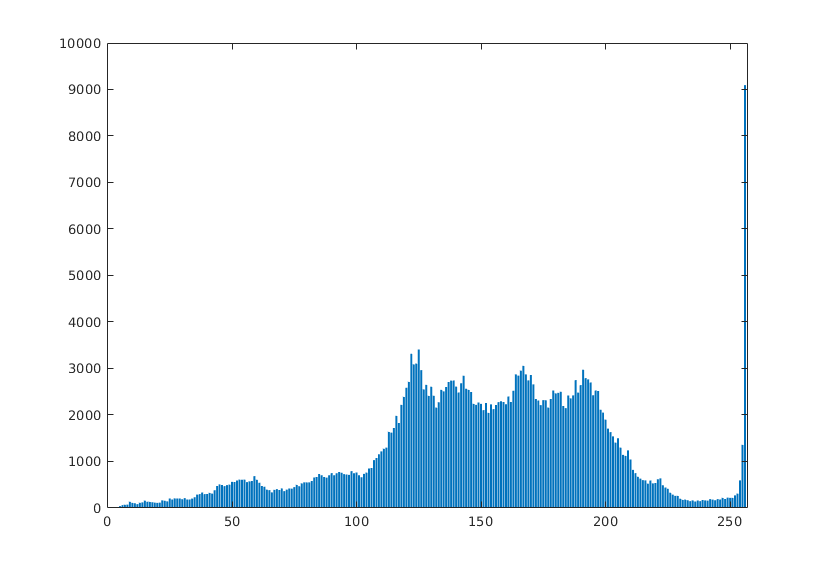

[histo,~]=imhist(imReducida);
bar(histo)

Con la ayuda del histograma calculamos la frecuencia acumulada de la imagen:

histoAcum = zeros(1,256);
histoAcum(1)=histo(1);
for i=2:length(histo)
    histoAcum(i)=histoAcum(i-1)+histo(i);
end

Y despues con estos datos hacemos el histograma acumulado Normalizado

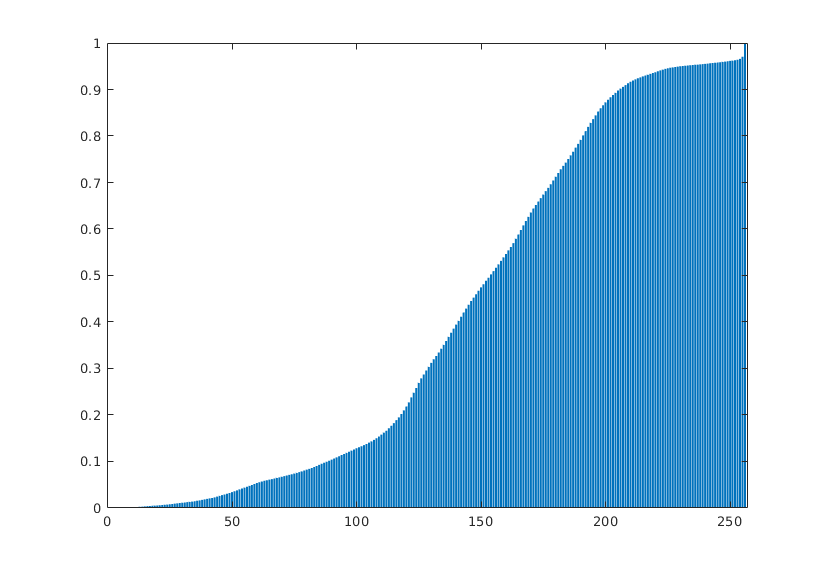

[r,c]=size(imReducida);
histoAcumNorma= histoAcum./(r*c);
bar(histoAcumNorma);

Una vez con el histograma acumulado normalizado, procedemos a ecualizar la imagen:

m = 255;
n = 0;
imEcualizada = zeros(r,c,'uint8');
for i = 1:r
    for j = 1:c
        imEcualizada(i,j)=uint8(histoAcumNorma(imReducida(i,j)+1)*m+n);
    end
end

%histograma final
histoEcualizado=zeros(1,256);
for i = 1:r
    for j = 1:c
        histoEcualizado(imEcualizada(i,j)+1) = histoEcualizado(imEcualizada(i,j)+1)+1;
    end
end

Con el código anterior obtenemos la imagen ecualizada:

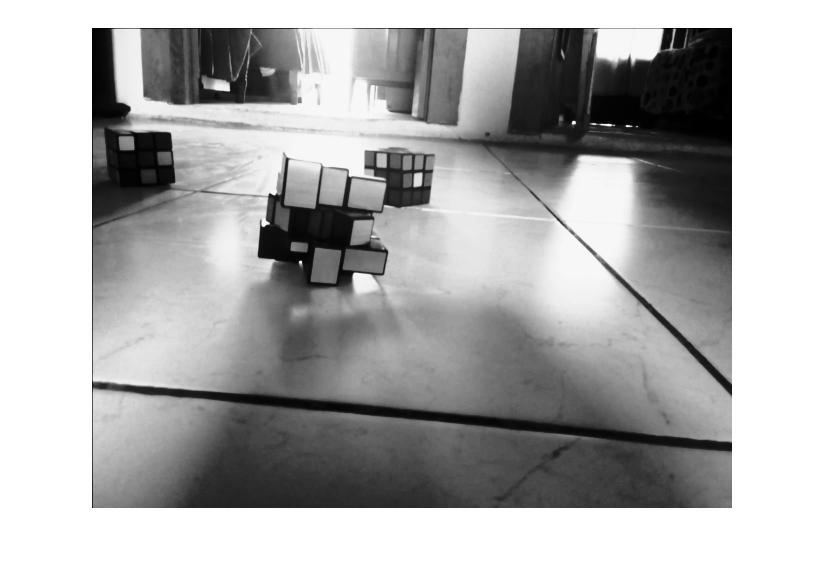

imshow(imEcualizada);

 y el histograma final:

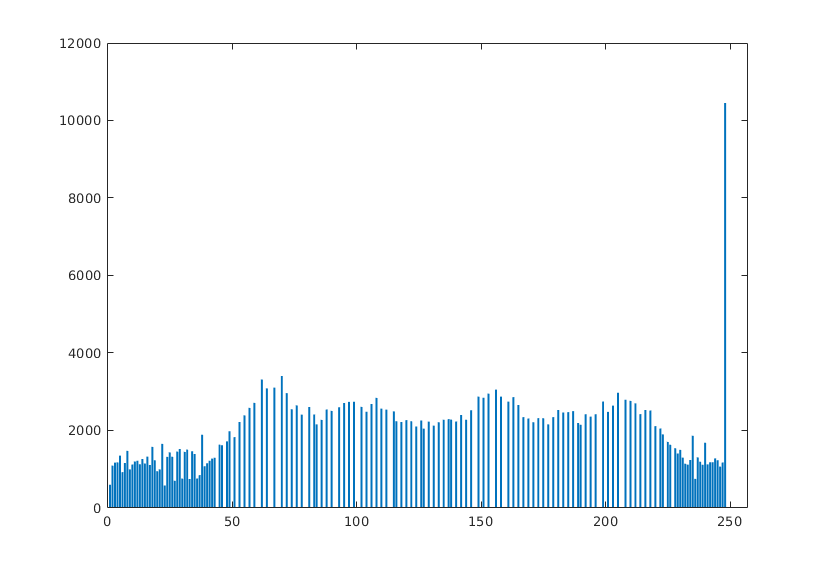

bar(histoEcualizado);

Por ultimo procedemos a calcular el HDR

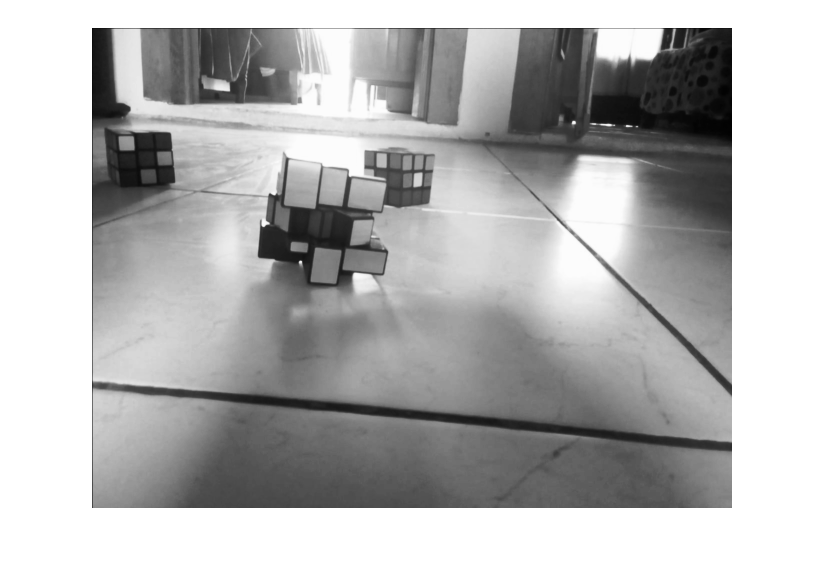

%HDR
imHDR = imReducida/2+imEcualizada/2;
imshow(imHDR);

## ***Filtro Mediana***

El filtro mediana nos ayudará a reducir el filtro de la imagen antes de hacer el calculo de Canny:

imMediana = zeros(r,c);
for i = 1:r
    for j = 1:c
        H = imHDR(max(i-1, 1):min(i+1,r), max(j-1, 1):min(j+1, c));
        imMediana(i,j) = median(median(H));
    end
end
imMediana = uint8(imMediana);

Obtenemos la imagen filtrada con reducción de ruido:

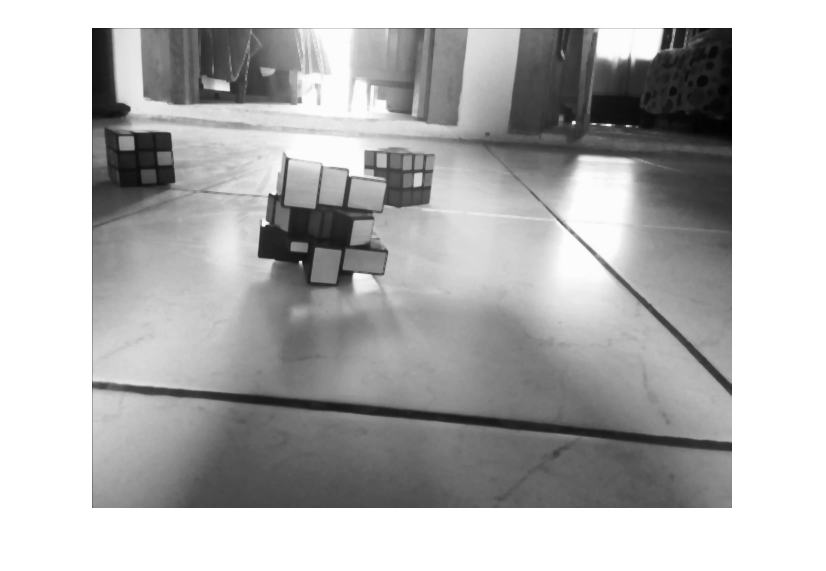

imshow(imMediana);

## ***Canny***

La aplicación del algoritmo Canny nos ayudará a obtener los bordes de la imagen, ya que la simple conversión de la imagen a blanco y negro no nos ayuda mucho a detectar objetos como podemos ver:

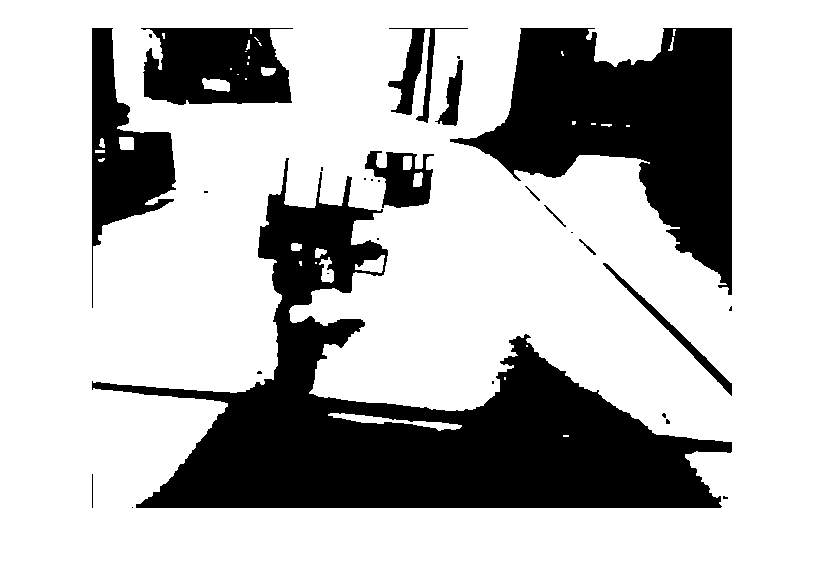

imshow(im2bw(imMediana,0.5))

Para realizar el algoritmo Canny utilizaremos el filtro de derivada Sobel